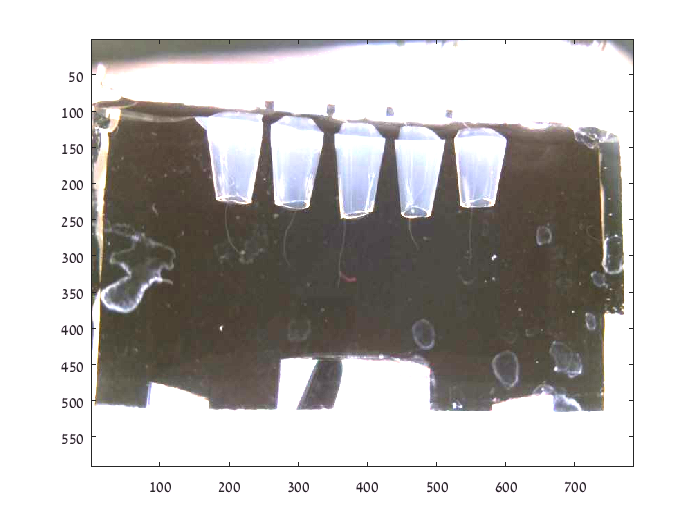

% Tweaking the extraction

clear variables
% For a fresh start
% Having a string with the file name
% file_name = 'Lychee_test1.jpg';
 file_name = 'Lychee_test2.jpg';
% file_name = 'Lychee_test3_2018-03-06_1630.jpg';
% file_name = 'Lychee_test4_2018-03-08_1220.jpg';


lych_tst2 = imread(file_name);
lych_tst2=double(lych_tst2) /255; % Converting to double
lych_tst2 = lych_tst2 * 3; % Multiplying by 3

image(lych_tst2)

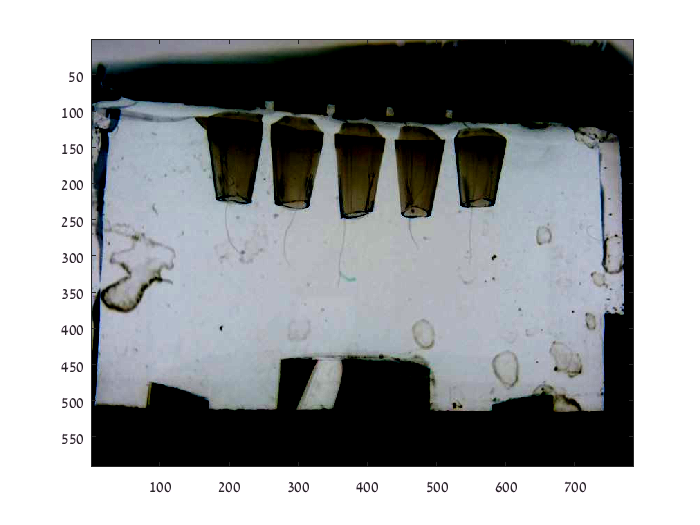


% Inverting the image
lych_tst2 = 1.- lych_tst2;

image(lych_tst2)

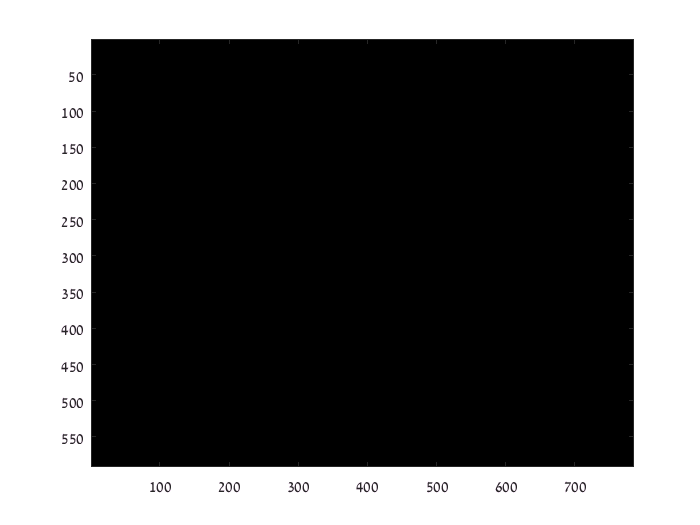



% TESTING the blind deconv and then the wienar one.

% First need a guess for the PSF. Documantation claims the size of the matrix is more important then the values so just throw 1's there
INITPSF = ones(12,1); % The 12 is a wild guess.

% Now getting a deblurred photo after the blind and a PSF to use with the other methods.
[nJ,nPSF] = deconvblind(lych_tst2,INITPSF);
image(nJ)

%showing the original photo
figure
image(lych_tst2); % Changed foe UPDATE**

%image(imcrop(lych_tst2));


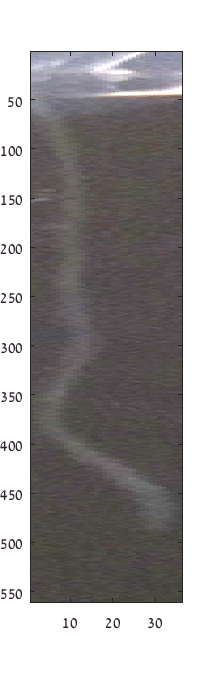

%% % Colour tweak

% UPDATE 16.718 12:06 - Now that we receive the poins from the user, we can
% do an initial color filtering based on the R G & B values of those
% points. After that, we will apply the gray-ing filter from before.
Imtst = lychcrop2;
image(Imtst)

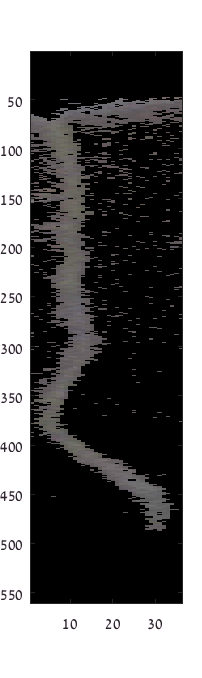

% Seperate to R G & B matrices
ImtstR=Imtst(:,:,1);
ImtstG=Imtst(:,:,2);
ImtstB=Imtst(:,:,3);

% Creating 3 filtering masks according to the three color ranges
filmaskR = ImtstR<cfiltR(1) | ImtstR>cfiltR(2);
filmaskG = ImtstG<cfiltG(1) | ImtstG>cfiltG(2);
filmaskB = ImtstB<cfiltB(1) | ImtstB>cfiltB(2);


% Applying the filtering masks to all 3 colour channels, ie set it to black
ImtstR(filmaskR)=0;
ImtstG(filmaskR)=0;
ImtstB(filmaskR)=0;
ImtstR(filmaskG)=0;
ImtstG(filmaskG)=0;
ImtstB(filmaskG)=0;
ImtstR(filmaskB)=0;
ImtstG(filmaskB)=0;
ImtstB(filmaskB)=0;

Imtst = cat(3, ImtstR, ImtstG, ImtstB); % Concatenating the seperate R G and B matrices to reproduce an altered image.
Imbacktst = Imtst; % I'll back it up for now until TESTING some of the things is over
image(Imtst)

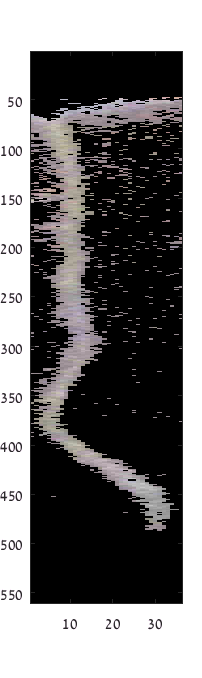

clear('filmaskR','filmaskG','filmaskB','rootx','rooty')
% We (no longer) start with the brightness based filteration in order to enhance the
% difference between the color channels

% Imtst = lychcrop2*3; % UNNECESSARY NOW that we have the filter above.

% Doing a scaled enhancment - everything that isn't black gets brighter,
% and the brighter you are the brighter you get
Imtst = Imtst.*1.1;
Imtst = Imtst.*1.1;
Imtst = Imtst.*(1.1+Imtst.^2);
image(Imtst)

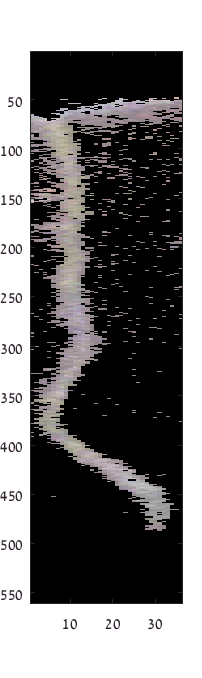


% Now performing RGB level difference based filtering. Basically, if the
% RGB components are too far apart the pixel is blackend

% First - R to G

% Creating the filtering mask
% test if difference between R and G channel are above threshold
filmask = (Imtst(:,:,1)-Imtst(:,:,2))>(1.21*mean([cfiltR(2)-cfiltR(1),cfiltG(2)-cfiltG(1)]));

% Seperate to R G & B matrices
ImtstR=Imtst(:,:,1);
ImtstG=Imtst(:,:,2);
ImtstB=Imtst(:,:,3);
% Applying the filtering mask to all 3 colour channels, ie set it to black
ImtstR(filmask)=0;
ImtstG(filmask)=0;
ImtstB(filmask)=0;

% rebuild RGB image
Imtst = cat(3, ImtstR, ImtstG, ImtstB); % Concatenating the seperate R G and B matrices to reproduce an altered image.
image(Imtst)

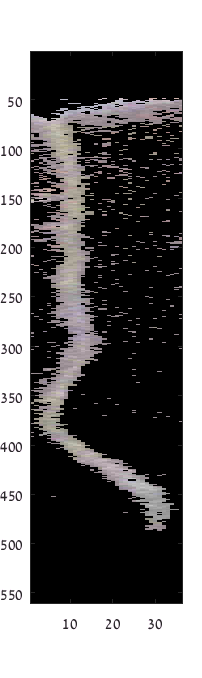

% Second - R to B

% Creating the filtering mask
filmask = (Imtst(:,:,1)-Imtst(:,:,3))>(1.21*mean([cfiltR(2)-cfiltR(1),cfiltB(2)-cfiltB(1)]));

% Seperate to R G & B matrices
ImtstR=Imtst(:,:,1);
ImtstG=Imtst(:,:,2);
ImtstB=Imtst(:,:,3);
% Applying the filtering mask to all 3 colors
ImtstR(filmask)=0;
ImtstG(filmask)=0;
ImtstB(filmask)=0;

Imtst = cat(3, ImtstR, ImtstG, ImtstB); % Concatenating the seperate R G and B matrices to reproduce an altered image.
image(Imtst)


% Third - G to B

% Creating the filtering mask
filmask = (Imtst(:,:,2)-Imtst(:,:,3))>(1.21*mean([cfiltB(2)-cfiltB(1),cfiltG(2)-cfiltG(1)]));

% Seperate to R G & B matrices
ImtstR=Imtst(:,:,1);
ImtstG=Imtst(:,:,2);
ImtstB=Imtst(:,:,3);
% Applying the filtering mask to all 3 colors
ImtstR(filmask)=0;
ImtstG(filmask)=0;
ImtstB(filmask)=0;

Imtst = cat(3, ImtstR, ImtstG, ImtstB); % Concatenating the seperate R G and B matrices to reproduce an altered image.
image(Imtst)

% Grayscaling it now
graywarden = rgb2gray(Imtst);

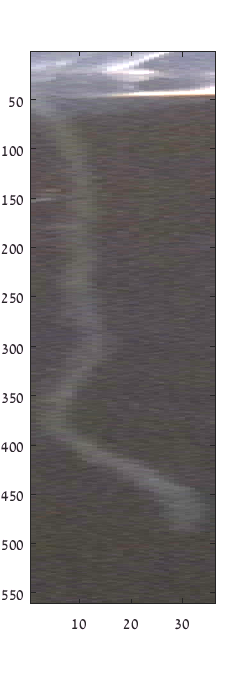

% Bright tweak
Imtstbri = lychcrop2;

% Grayscaling it. Sooner than before, and maybe the whole loop will become
% obsolete.
brighttst = rgb2gray(Imtstbri);

% Creating a filtering mask according to the brightness rang.
filmask = brighttst<brighfilt(1) | brighttst>brighfilt(2);

brighttst(filmask)=0;

% % Eliminating too bright cells.
% Imtstbri(Imtstbri>0.55)=0;
% OBSOLETE now that we have the filter above it.
scalfilt = brighfilt;
image(Imtstbri)

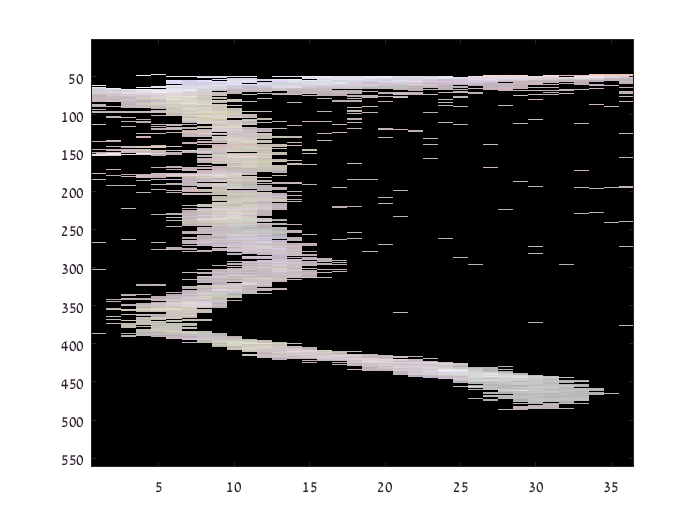


figure
hold on
for i=1:7
    % Multiplication and elimination of >1
    Imtstbri = Imtstbri * 1.1;
    % Filtering on all color channels.
    % We check which color values have value over 1.
    scalfilt = scalfilt * 1.1;
    afilmask = Imtstbri>1 | Imtstbri<scalfilt(1);
    % Then we create a filter which is 0 if even on of the channels is over
    % 1.
    filmask = (1.-afilmask(:,:,1)).* (1.-afilmask(:,:,2)).* (1.-afilmask(:,:,3));
    % Then we apply the mask to all color channels
    Imtstbri(:,:,1) = Imtstbri(:,:,1) .* (filmask);
    Imtstbri(:,:,2) = Imtstbri(:,:,2) .* (filmask);
    Imtstbri(:,:,3) = Imtstbri(:,:,3) .* (filmask);
    
end
hold off
image(Imtstbri)

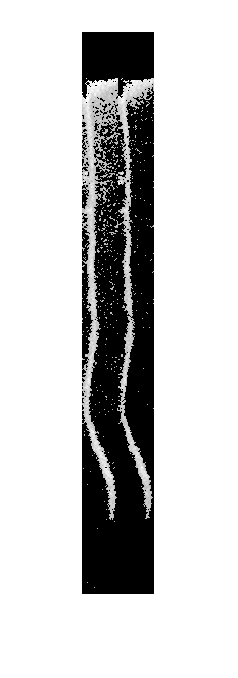

bright2 = rgb2gray(Imtstbri);
imshowpair(brighttst,bright2,'montage')

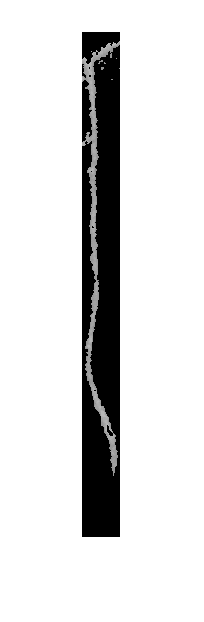

%% %skeletor tweak
imshow(graywarden)

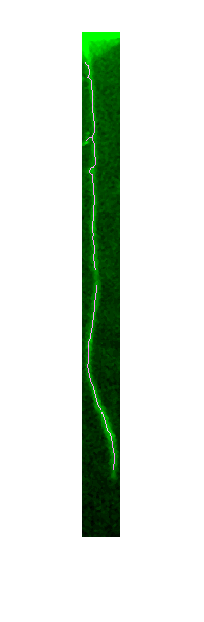

% Trying to use fibermetric to get rid of the annoying thorns without
% sacrifiacing root. Hopefully, it will make the rest of the section become
% better. First imfill though
skeletor = imfill(graywarden,'holes');
skeletor = fibermetric(skeletor,20, 'StructureSensitivity', 0.02);

%Some Testing showed that
% bwareaopen(imbinarize(wiener2(imfill(skeletor,'holes'),[1 12]),'adaptive','Sensitivity',0.45),400)
% is very good, so we will do the necessary steps (16.7.18 18:56)

skeletor = imfill(skeletor,'holes');
skeletor = wiener2(skeletor,[1 3]); 
% The last added step is after the binarization.
% % Doing a set of binarizing, getting rid of isolated points, filling stuff
% % and then skeletonizing and other methods. One of the differnces from
% before are the 2 steps above.
skeletor=imbinarize(skeletor,'adaptive','Sensitivity',0.6);
% UPDATE - Added the wiener2 noise filtering function

% Last new step
skeletor = bwareaopen(skeletor,400);

skeletor = medfilt2(skeletor);
% Added the medfilt2 filtering function to try and improve the process to
% exclude closed rings (loops) and such


% fill in holes in the binarised image
skeletor = imfill(skeletor,'holes');
% clean isolated pixels until image series converges  -- DOES NOT CHANGE MUCH, sort of safety measure
skeletor = bwmorph(skeletor,'clean',Inf);
% get rid of isolated non-root structures (< 35 pixels), BUT BE CAREFUL: WE CAN
% DESTROY ROOTS
% Added another one before skeletization
skeletor = bwareaopen(skeletor,200);

%  extract skeleton
skeletor=bwmorph(skeletor,'skel',Inf);
% fill in holes b/c skeltetisation creates holes sometimes
skeletor=imfill(skeletor,'holes');
% close small gaps
skeletor=bwmorph(skeletor,'bridge',Inf);
% get rid of isolated non-root structures (< 35 pixels), BUT BE CAREFUL: WE CAN
% DESTROY ROOTS
skeletor=bwareaopen(skeletor,35);



% destroy small branches -- BE CAREFUL: IN PICTURE2 DESTROYS ROOTS --- FIX IT.
skeletor = bwmorph(skeletor,'spur',5); 

% get rid of isolated non-root structures (< 35 pixels), BUT BE CAREFUL: WE CAN
% DESTROY ROOTS
skeletor=bwareaopen(skeletor,35);


%  figure
  imshowpair(lychcrop2*2,skeletor); %TEST